Script to plot the numerical solution for y(x) of the given second-order ODE 

**y''(x) = (-g/L)*sin(y(x))** using Euler's method and ode45. We're given that g = 9.81, L = 1, y(0) = π/2, y'(0) = 0 and we're using step size h = 0.005

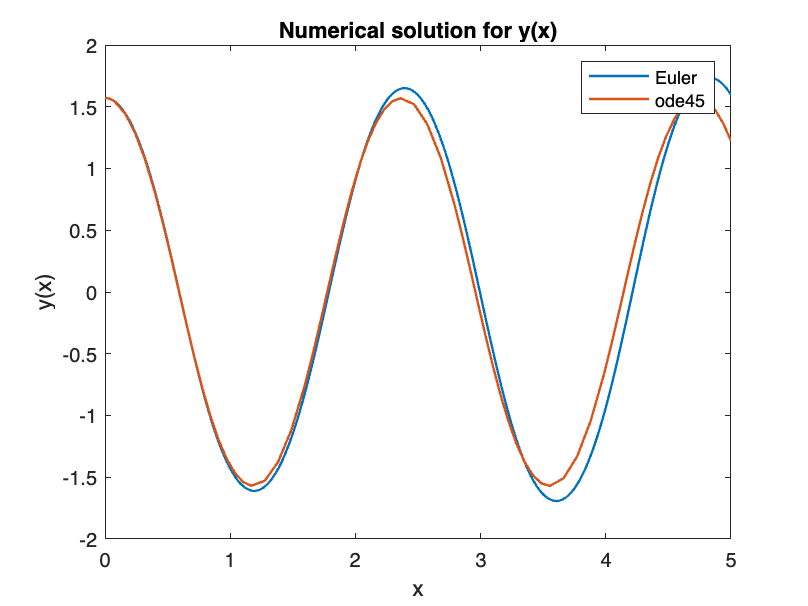

g = 9.81; L = 1;
x0 = 0; X = 5; h = 0.005;
y0 = [pi/2;0];
xspan = [x0;X];
x = (x0:h:X);
n = numel(x);
f = zeros(2,n);
f(:,1) = y0;
for i = 2:n
    dydx = odefcn(x(i-1),f(:,i-1));
    f(:,i) = f(:,i-1) + h*dydx;
end

[xode,yode] = ode45(@odefcn,xspan,y0);

plot(x,f(1,:),'Linewidth',1.2);
hold on
plot(xode,yode(:,1),'Linewidth',1.2);
legend('Euler','ode45');
title('Numerical solution for y(x)');
xlabel('x'); ylabel('y(x)');
hold off

function dydx = odefcn(~,y)
g = 9.81; L = 1;
dydx = [y(2); (-g/L)*sin(y(1))];
end